Names = {'50Hz_200kHz_encoder.txt'};
Legend = {'Энкодер'};

N_signals = length(Names);
N = length(Names);
F_s = length(Names);
Time = length(Names);

for i=1:N_signals
    file = Names{i};
    headerLength = 19;
    fid = fopen(file);
    
    if fid == -1 
        error('File could not be opened, check name or path.')
    end
    
    header = cell(headerLength, 1);
    for j = 1:headerLength
        header{j} = fgetl(fid);
    end
    fclose(fid);
    fid = fopen(file);
    
    N(i) = str2double(header{3}(19:end));
    F_s(i) = str2double(header{8}(20:end))*1e3;
    Time(i) = str2double(header{9}(20:end));
end

time_temp = cell(N_signals, 1);
data_temp = cell(N_signals, 1);

F_s = max(F_s);
Time = linspace(0, max(Time), max(N));
Data = zeros(max(N), N_signals);

for i=1:N_signals
    file = Names{i};
    headerLength = 19;
    fid = fopen(file);
    
    if fid == -1 
        error('File could not be opened, check name or path.')
    end
    
    header = cell(headerLength, 1);
    for j = 1:headerLength
        header{j} = fgetl(fid);
    end
    fclose(fid);
    fid = fopen(file);

    numColumns = 1;
    data_temp{i} = cell2mat(textscan(fid, repmat('%f',1,numColumns), 'headerlines', headerLength));

    Data(:,i) = data_temp{i};

    fclose(fid);
end
N = max(N);

График сигнала во временной области

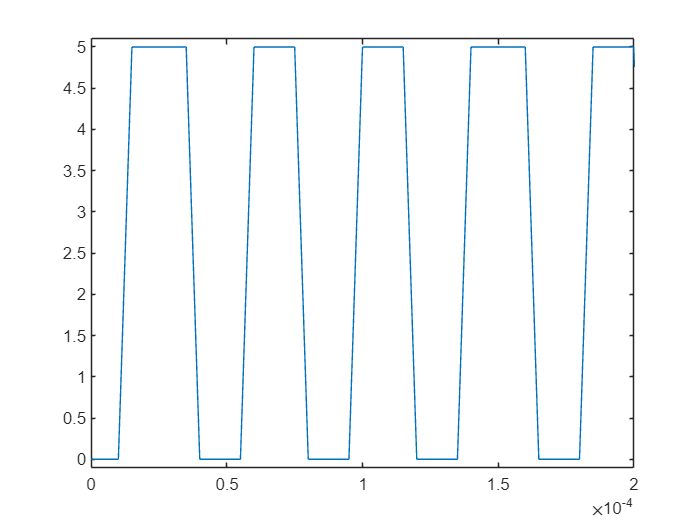

Data(Data<1) = 0;
Data(Data>=1) = 5;

plot(Time, Data)
xlim([0; 0.0002])
ylim([-0.1; 5.1])


Up = [];
j = 0;
for i=2:N
    if Data(i) == 5 && Data(i-1)==0
        j = j+1;
        Up(j) = Time(i);
    end
end

Freq = 1/(median(Up-circshift(Up,1)))/1024

Freq = 24.4139